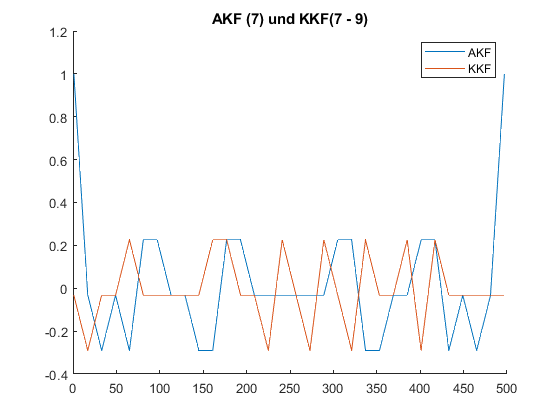

clear();
%{
******************** 
******** a *********
********************
%}

SEQ_LENGTH = 31;
OVERSAMPLING = 16;

mSequence = get_m_sequences(SEQ_LENGTH, OVERSAMPLING);
pairs = find_pairs(SEQ_LENGTH);
pairsLength = length(pairs);

%{
******************** 
******** b *********
********************
%}

% finde alle Indexe die einen 1er enhalten
onesIndecies = find(pairs);
% Wenn es keine gibt dann brich ab
if isempty(onesIndecies)
    return;
end

border = 7;
[col,row] = ind2sub(pairsLength, onesIndecies(1));
goldCodes = gold_seq(SEQ_LENGTH, row, col, OVERSAMPLING);
periodicAkf = kkf_per(goldCodes(:, border),goldCodes(:, border));
periodicKkf = kkf_per(goldCodes(:, border),goldCodes(:, 9));

%Plotten der AKF und KKF
figure;
hold on;
plot(periodicAkf);
plot(periodicKkf);
legend('AKF','KKF');
title(sprintf('AKF (%i) und KKF(%i - 9)' , border, border));
hold off;

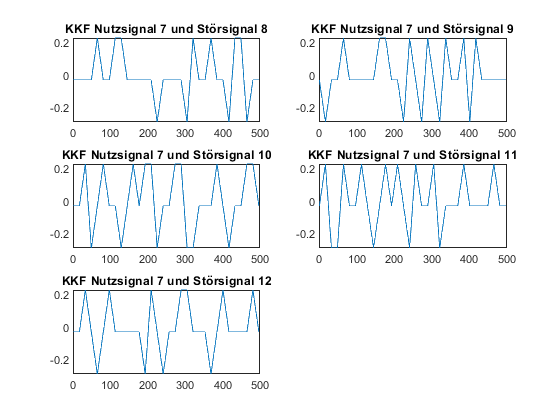


%{
******************** 
******** c *********
********************
%}

goldCodesSize = size(goldCodes);
clutterPeriodicKkf = zeros([goldCodesSize(1) + 1, goldCodesSize(2)]);
figure;
%6 Signale, 5 Störsignale
for i = 8:12
    subplot(3,2, i-border);
    clutterPeriodicKkf(:, i-border) = kkf_per(goldCodes(:, border),goldCodes(:, i));
    plot(clutterPeriodicKkf(:, i-border));
    title(sprintf('KKF Nutzsignal %i und Störsignal %i', border, i));
end

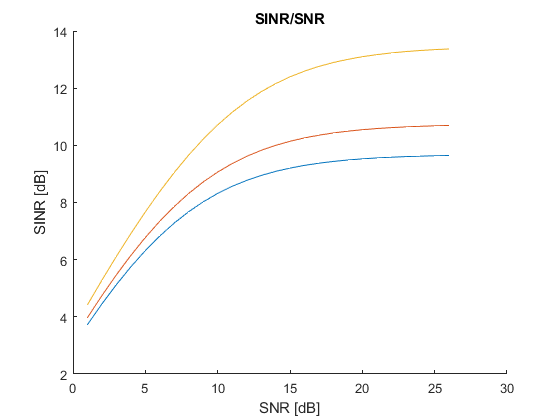


%{
******************** 
******** d *********
********************
%}

figure;
hold on;

J = 6;
Gp = SEQ_LENGTH;
%Sendeleistung
S = 1;

dbSNR = 5:30; 
SNR = 10.^(dbSNR./10);
N = S./SNR;

rectSINR = Gp./((J-1)*(2/3)+(Gp./SNR));
dbRectSINR= 10*log10(rectSINR);

plot(dbRectSINR);

I = sum(mean(clutterPeriodicKkf.^2));
SINR = S./(N + I);
dbSINR = 10*log10(SINR);

plot(dbSINR);

%{
******************** 
******** e *********
********************
%}

clutterAPeriodicKkf = zeros([2 * goldCodesSize(1) - 1, length(goldCodesSize(2))]);

for i = 8:12
    clutterAPeriodicKkf(:, i-border) = kkf_aper(goldCodes(:, border),goldCodes(:, i));
end

I = sum(mean(clutterAPeriodicKkf.^2));
SINR = S./(N + I);
dbSINR = 10*log10(SINR);

plot(dbSINR);

xlabel('SNR [dB]');
ylabel('SINR [dB]');
title('SINR/SNR');
hold off;